% === 参数设置 ===
close all; clear; clc
j = sqrt(-1);

fs = 80e6;           % 采样频率
ts = 1/fs;
B = 10e6;            % 带宽
fc = 40e6;           % 中心频率
label = 7;

% === LFM脉冲 ===
taup = 10e-6;        % LFM脉宽
Ntau = round(taup * fs);
ttau = (-Ntau/2 : Ntau/2-1) * ts;
lfm = exp(1j*pi*B/taup * ttau.^2);  % 基带LFM脉冲

% === 多脉冲参数 ===
Np = 16;                 % 脉冲个数
PRI = 200e-6;            % 脉冲重复间隔 200 μs
PRI_samp = round(PRI * fs);   % 每个PRI的采样点
N_total = Np * PRI_samp;      % 总采样点数
t_total = (0:N_total-1) * ts; % 时间轴

% === 构造发射信号 ===
tx = zeros(1, N_total);
for k = 0:Np-1
    start_idx = k * PRI_samp + 5000;
    tx(start_idx : start_idx + Ntau - 1) = lfm;
end

% === 模拟噪声与干扰 ===
SNR = 15;
JNR = 50;
Bj = 5e6;  % 扫频带宽
fjc = 0;   % 干扰中心频率
data_num = 3 %干扰样本数

data_num = 3

As = 10^(SNR/20);
Aj = 10^(JNR/20);

jam = zeros(data_num,N_total);
for m = 1:data_num
sp = randn([1,N_total]) + 1j*randn([1,N_total]);
sp = sp / std(sp);
white_noise = sp;

% === 生成扫频干扰 ===
T_sweep=20*1e-6+round((rand(1,1)*20))*1e-6;%扫频周期20-40us
B1 = 8*Bj
f0 = -B1/2;                % 起始频率（相对基带）
K = B1 / T_sweep;          % 调频斜率
tj = (0:N_total-1)/fs;     % 时间轴

% 将时间折返到每个扫频周期内
t_mod = mod(tj, T_sweep);

% 生成扫频载波（周期性线性调频）
sweep_carrier = exp(1j*2*pi*(f0*t_mod + 0.5*K*t_mod.^2));

% 叠加宽带噪声包络（可选）
sp = randn([1,N_total]) + 1j*randn([1,N_total]);
sp = sp / std(sp);
lpFilt = fir1(34, Bj/fs, chebwin(35,30));
sp_env = filter(lpFilt, 1, sp);

% 扫频干扰信号
sp_j = Aj * sweep_carrier .* sp_env;

jam(m,:) = sp_j;

end

B1 = 40000000

B1 = 40000000

B1 = 40000000

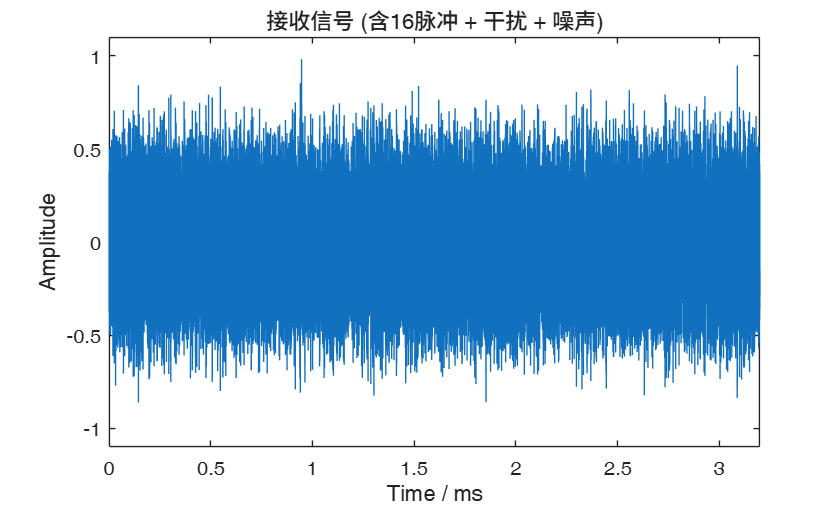


% --- 加入目标与干扰 ---
range_tar = 1 + round(rand(1)*4000);
jam1 = Aj*sp_j;
pure_echo = As*tx;
rx = As*tx + Aj*sp_j + white_noise;
rx = rx / max(abs(rx));

figure;
plot(t_total*1e3, real(rx));
axis([0 3.2 -1.1 1.1])
xlabel('Time / ms'); ylabel('Amplitude');
title('接收信号 (含16脉冲 + 干扰 + 噪声)');

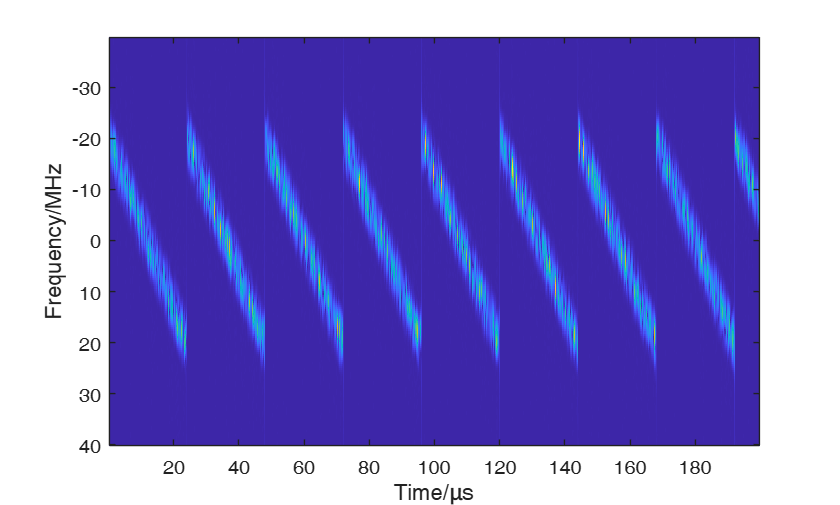


figure;
[S,F,T] = spectrogram(rx(1:PRI_samp),32,32-8,200,fs, 'centered');
imagesc(T*1e6,F/1e6,abs(S));
% axis([0 100 -20 20])
ylabel('Frequency/MHz'); xlabel('Time/μs');


% === 匹配滤波（脉冲压缩） ===
h = conj(flip(lfm));
y = conv(rx, h);
env = abs(y);

% === 脉冲积累（非相干示例） ===
env_mat = reshape(env(1:Np*PRI_samp), PRI_samp, Np); % 每列一个脉冲
env_sum = abs(sum(env_mat, 2));  % 直接复数相加再取幅度
nenv_mat = reshape(y(1:Np*PRI_samp), PRI_samp, Np); % 每列一个脉冲
nenv_sum = sum(nenv_mat, 2); % 非相干积累

% 距离轴
c = 3e8;
rng_axis = (0:PRI_samp-1)*c/(2*fs);

